clear all
close all
clc

seedVal = 2; %2
rng(seedVal) 

%% Create a network object
network = Network(0);

% Number of subsystems
numOfSubsystems = 5; % 5
dimentionOfSpace = 2;
sizeOfSpace = 1;
communicationRadius = 0.9; %0.9

% subsystem dims
for i = 1:1:numOfSubsystems
    dims{i}.n = 2; % x
    dims{i}.p = 1; % u
    dims{i}.q = 1; % w  
    dims{i}.m = 1; % y
    dims{i}.l = 1; % z 
end

% Diagonal matrices out of Network Matrices: A,B,C,D,E,F,G,H,J,Q,S,R 
% (1 if true, -1 % if zero and 0 if false)
diags = [0,1,1,-1,0,1,1,1,1] % respectively for 

diags =      0     1     1    -1     0     1     1     1     1


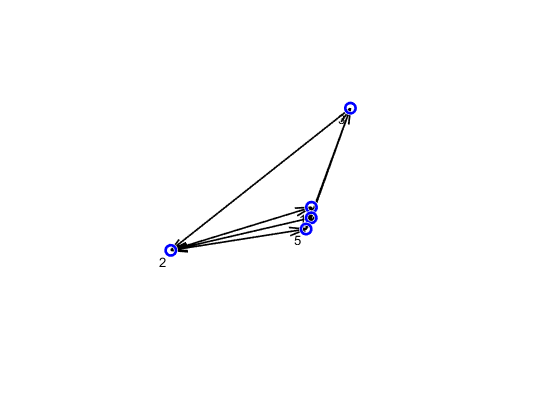


% Create the network and plot it
network = network.loadARandomNetwork(numOfSubsystems,dimentionOfSpace,sizeOfSpace,communicationRadius,dims,diags);
network.shiftLocations();
network.drawNetwork(1,false);


% Get network matrices
[A,B,C,D,E,F,G,H,J,x] = network.getNetworkMatrices()

A =    -6.9853    1.8664   -0.0746    0.0583         0         0   -0.0164   -0.1886   -0.1032   -0.3196
    1.8664   -1.7350    0.0583   -0.1033         0         0    0.1886   -0.0164    0.3196   -0.1032
         0         0   -0.6886   -0.0736   -0.0544   -0.2461   -0.0299   -0.1088   -0.3319   -0.2719
         0         0   -0.0736   -0.7741    0.2461   -0.0544    0.1088   -0.0299   -0.2719   -0.3078
         0         0         0         0   -0.6499    0.0018   -0.1100   -0.0584   -0.1859    0.0016
         0         0         0         0    0.0018   -0.6534   -0.0584   -2.1393    0.0016   -0.1707
   -0.0306    0.0018         0         0         0         0   -0.6166    0.2366   -0.1501   -0.4925
    0.0018   -0.0526         0         0         0         0    0.2366   -1.9330    0.4925   -0.1501
         0         0   -0.0899    0.0065   -0.0056    0.0099         0         0   -0.9023    0.0477
         0         0    0.0065   -0.1976    0.0099   -0.0176         0         0    0.0

B =          0         0         0         0         0
   -0.3859         0         0         0         0
         0    0.4197         0         0         0
         0    0.8255         0         0         0
         0         0   -0.9853         0         0
         0         0         0         0         0
         0         0         0    0.3540         0
         0         0         0         0         0
         0         0         0         0    1.4348
         0         0         0         0         0


C =          0   -0.3172         0         0         0         0         0         0         0         0
         0         0   -1.2030    0.6372         0         0         0         0         0         0
         0         0         0         0         0   -0.0151         0         0         0         0
         0         0         0         0         0         0   -2.0408    0.7012         0         0
         0         0         0         0         0         0         0         0   -0.8138         0


D =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


E =    -0.0059    0.0020         0   -0.0099   -0.0020
    0.0006   -0.0025         0         0    0.0076
         0    0.0054         0         0   -0.0044
         0         0    0.0005   -0.0096   -0.0049
         0         0    0.0039    0.0053    0.0050
         0         0    0.0024   -0.0110         0
   -0.0048         0         0   -0.0041   -0.0030
         0         0         0   -0.0073   -0.0010
         0    0.0050   -0.0054         0    0.0042
         0    0.0063    0.0067         0    0.0131


F =     0.0188         0         0         0         0
         0         0         0         0         0
         0         0    0.0105         0         0
         0         0         0   -0.0019         0
         0         0         0         0         0


G =      1     1     0     0     0     0     0     0     0     0
     0     0     1     1     0     0     0     0     0     0
     0     0     0     0     1     1     0     0     0     0
     0     0     0     0     0     0     1     1     0     0
     0     0     0     0     0     0     0     0     1     1


H =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


J =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


x =     5.6338
    8.7656
    6.9424
    1.3976
    7.0936
    4.4628
    1.9485
    7.9500
    6.8448
    6.5043


n = size(A,1)

n = 10

p = size(B,2)

p = 5

q = size(E,2)

q = 5



% Generate Q,S,R matrices
dissFrom = 'w';    % Options: 'u', 'w'
dissTo = 'z';      % Options: 'y', 'z'
dissType = 'strictly passive';     % Options: strictly passive([IFP, OFP]), passive, L2G(gamma), random 
dissArgs = [0.2,0.2] %[0,0.01]

dissArgs =     0.2000    0.2000


% dissType = 'passive';
% dissArgs = 0;
[Q,S,R] = network.getSomeQSRMatrices(dissFrom,dissTo,dissType,dissArgs) 

Q =    -0.2000         0         0         0         0
         0   -0.2000         0         0         0
         0         0   -0.2000         0         0
         0         0         0   -0.2000         0
         0         0         0         0   -0.2000


S =     0.5000         0         0         0         0
         0    0.5000         0         0         0
         0         0    0.5000         0         0
         0         0         0    0.5000         0
         0         0         0         0    0.5000


R =    -0.2000         0         0         0         0
         0   -0.2000         0         0         0
         0         0   -0.2000         0         0
         0         0         0   -0.2000         0
         0         0         0         0   -0.2000


network.storeQSRMatrices(Q,S,R); % Store information locally at each sub-system

Centralized Stability Based Concepts

% addpath('C:\Program Files\Mosek\9.3\toolbox\R2015a')
solverOptions = sdpsettings('solver','mosek');
rng(seedVal);

% % % % Stability Analysis
isStable = network.centralizedStabilityAnalysis(solverOptions)

MOSEK Version 9.3.16 (Build date: 2022-3-2 13:37:03)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : min             
  Type                   : CONIC (conic optimization problem)
  Constraints            : 15              
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 2               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number                 : 0               
Presolve terminated. Time: 0.00    
Problem
  Name   

isStable = logical
   1



% % % % Stabilization using FSF control
[KStab,isFSFStabilizable] = network.centralizedFSFStabilization(solverOptions)

MOSEK Version 9.3.16 (Build date: 2022-3-2 13:37:03)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : min             
  Type                   : CONIC (conic optimization problem)
  Constraints            : 49              
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 2               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number                 : 0               
Presolve terminated. Time: 0.02    
Problem
  Name   

KStab =    24.5531   -5.5327    0.1511   -0.2677         0         0    0.0360   -0.5073    0.8284   -0.2674
         0         0    0.1852    0.2881   -0.2103    0.1727   -0.0900    0.0846    0.0658    1.7487
         0         0         0         0   -0.1186    0.0819   -0.1015   -0.0559   -0.0349    0.0002
    0.5602   -0.4980         0         0         0         0    0.2457   -3.1304    0.4314    1.4919
         0         0    0.2307    0.1008    0.0930    0.1290         0         0    0.1063   -0.0944


isFSFStabilizable = logical
   1



% % % % Stable observer design
[LStab,isObserverStable] = network.centralizedStableObserverDesign(solverOptions)

MOSEK Version 9.3.16 (Build date: 2022-3-2 13:37:03)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : min             
  Type                   : CONIC (conic optimization problem)
  Constraints            : 49              
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 2               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number                 : 0               
Presolve terminated. Time: 0.00    
Problem
  Name   

LStab =   -29.5202    0.0622         0   -0.0477    0.1268
    6.6146   -0.0731         0   -0.0059   -0.3928
         0    0.0855   14.8954   -0.0260    0.1444
         0    0.0009    4.6083   -0.0960    0.5486
         0         0   -5.1389    0.0399    0.2364
         0         0  -77.7706   -0.3044    0.0101
   -0.7992         0         0   -0.0847    0.1845
    0.2586         0         0   -0.6534   -0.6052
         0    0.2472   -0.8815         0    0.4950
         0    0.3389    1.7174         0   -0.2847


isObserverStable = logical
   1



% % % % Stabilization using DOF control
[AcStab,BcStab,CcStab,DcStab,isDOFStabilizable] = network.centralizedDOFStabilization(solverOptions) 

MOSEK Version 9.3.16 (Build date: 2022-3-2 13:37:03)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : min             
  Type                   : CONIC (conic optimization problem)
  Constraints            : 166             
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 4               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number                 : 0               
Presolve terminated. Time: 0.00    
Problem
  Name   

AcStab =    -9.4724  -33.9424    0.0008    0.0021         0         0    0.3067    0.0532   -0.0000   -0.1710
   -0.8134    1.7159   -0.0018    0.0052         0         0   -0.1027   -0.0746   -0.0000   -0.2878
         0         0   -0.5279   -0.0035   -0.1516   -0.0200   -0.0845   -0.1052    0.1491    0.9851
         0         0    0.0313   -0.5188    0.0698    0.0740   -0.0853    0.0976    0.2013    3.0244
         0         0         0         0   -0.5265   -0.1584    0.0012    0.0243    0.0178    0.0869
         0         0         0         0    0.0162   -1.4062   -0.4020   -1.5826   -0.0079   -0.4686
    0.0190    0.2221         0         0         0         0   -0.7012   -0.6674   -0.0022    0.1322
   -0.0335   -0.0087         0         0         0         0   -0.8274   -1.5992    0.0006   -0.5094
         0         0    0.2049   -0.0063    0.0129    0.3359         0         0   -0.7979   -0.8881
         0         0    0.0561   -0.0889   -0.0000    0.0542         0         0  

BcStab =   -23.7954   -0.0890         0   -1.4890   -0.1683
   66.9862   -0.1201         0    0.4839   -0.2836
         0   -0.9457 -129.2769    0.0572   -4.9558
         0    0.3676   31.1845    0.6271   -2.8956
         0         0   30.9857   -0.0583   -0.4336
         0         0  331.6658    2.0182    0.1284
    1.1699         0         0    0.9309   -0.2440
   -0.1447         0         0    5.4169    5.1578
         0   -0.2926   23.7323         0    1.6207
         0   -0.5578  -27.8538         0    0.5881


CcStab =    -2.2628   -8.3466    0.0073    0.0150         0         0    0.0599    0.0033    0.0000    0.1076
         0         0   -0.0149   -0.0312    0.0189   -0.0029   -0.0015   -0.0057   -0.0225   -0.5163
         0         0         0         0    0.0119   -0.0076    0.0015    0.0090    0.0011    0.0060
   -0.0280   -0.0846         0         0         0         0   -0.0070    0.2855    0.0005   -0.5894
         0         0   -0.0152   -0.0009   -0.0011   -0.0183         0         0    0.0167    0.0595


DcStab =     3.7568   -0.1901         0   -0.5268   -1.0179
         0   -0.0179   -9.9076    0.0522   -0.0719
         0         0   -0.3028    0.0412    0.2003
    0.3132         0         0   -0.1244   -0.5412
         0   -0.0029   -1.2985         0   -0.4380


isDOFStabilizable = logical
   1


Centralized Dissipativity Based Results

dissFrom = 'w'; dissTo = 'y';  
% dissType = 'strictly passive'; %dissArgs = [0.00001,1];
[Q,S,R] = network.getSomeQSRMatrices(dissFrom,dissTo,dissType,dissArgs) % dissFrom,dissTo,dissType,dissArgs

Q =    -0.2000         0         0         0         0
         0   -0.2000         0         0         0
         0         0   -0.2000         0         0
         0         0         0   -0.2000         0
         0         0         0         0   -0.2000


S =     0.5000         0         0         0         0
         0    0.5000         0         0         0
         0         0    0.5000         0         0
         0         0         0    0.5000         0
         0         0         0         0    0.5000


R =    -0.2000         0         0         0         0
         0   -0.2000         0         0         0
         0         0   -0.2000         0         0
         0         0         0   -0.2000         0
         0         0         0         0   -0.2000



% % % % Dissipativity Analysis
isDissipative = network.centralizedDissipativityAnalysis(dissFrom,dissTo,Q,S,R,solverOptions)

MOSEK Version 9.3.16 (Build date: 2022-3-2 13:37:03)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : min             
  Type                   : CONIC (conic optimization problem)
  Constraints            : 15              
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 2               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number                 : 0               
Presolve terminated. Time: 0.00    
Problem
  Name   

isDissipative = logical
   0



% % % % Dissipativation using FSF control
[KDiss,isFSFDissipative] = network.centralizedFSFDissipativation(dissFrom,dissTo,Q,S,R,solverOptions)

MOSEK Version 9.3.16 (Build date: 2022-3-2 13:37:03)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : min             
  Type                   : CONIC (conic optimization problem)
  Constraints            : 49              
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 2               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number                 : 0               
Presolve terminated. Time: 0.02    
Problem
  Name   

KDiss = 	1.0e+07 *

    0.0000    0.1951    0.0002   -0.0001         0         0   -0.0192    0.0060    0.0002    0.0000
         0         0    0.2603   -0.1379    0.0000   -0.0000   -0.0099    0.0034   -0.0233    0.0000
         0         0         0         0    0.0001    0.0008    0.0143   -0.0048    0.0090    0.0010
    0.0000   -0.0036         0         0         0         0   -1.3324    0.4577    0.0033   -0.0000
         0         0   -0.0237    0.0126    0.0000    0.0000         0         0   -0.1086    0.0000


isFSFDissipative = logical
   0



% % % % Dissipative observer design
dissFrom = 'w'; dissTo = 'z';  
% dissType = 'strictly passive'; %dissArgs = [0.00001,1];
[Q,S,R] = network.getSomeQSRMatrices(dissFrom,dissTo,dissType,dissArgs) % dissFrom,dissTo,dissType,dissArgs

Q =    -0.2000         0         0         0         0
         0   -0.2000         0         0         0
         0         0   -0.2000         0         0
         0         0         0   -0.2000         0
         0         0         0         0   -0.2000


S =     0.5000         0         0         0         0
         0    0.5000         0         0         0
         0         0    0.5000         0         0
         0         0         0    0.5000         0
         0         0         0         0    0.5000


R =    -0.2000         0         0         0         0
         0   -0.2000         0         0         0
         0         0   -0.2000         0         0
         0         0         0   -0.2000         0
         0         0         0         0   -0.2000


[LDiss,isObserverDissipative] = network.centralizedDissipativeObserverDesign(dissFrom,dissTo,Q,S,R,solverOptions)

MOSEK Version 9.3.16 (Build date: 2022-3-2 13:37:03)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : min             
  Type                   : CONIC (conic optimization problem)
  Constraints            : 49              
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 2               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number                 : 0               
Presolve terminated. Time: 0.00    
Problem
  Name   

LDiss =   -27.6557    0.0730         0    0.0099    0.1364
    5.9313   -0.0720         0   -0.0872   -0.3830
         0   -0.0032    4.8098   -0.0222    0.1484
         0   -0.0841    1.6121   -0.0925    0.5465
         0         0  -11.6753    0.0404    0.2357
         0         0  -56.1012   -0.3029    0.0002
   -0.1978         0         0   -0.1291    0.2022
    0.0501         0         0   -0.7080   -0.6066
         0    0.2356   -0.5513         0    0.4305
         0    0.3058    1.4817         0   -1.1437


isObserverDissipative = logical
   1



% % % % Stabilization using DOF control
dissFrom = 'w'; dissTo = 'z';  
% dissType = 'strictly passive'; %dissArgs = [0.00001,1];
[Q,S,R] = network.getSomeQSRMatrices(dissFrom,dissTo,dissType,dissArgs) % dissFrom,dissTo,dissType,dissArgs

Q =    -0.2000         0         0         0         0
         0   -0.2000         0         0         0
         0         0   -0.2000         0         0
         0         0         0   -0.2000         0
         0         0         0         0   -0.2000


S =     0.5000         0         0         0         0
         0    0.5000         0         0         0
         0         0    0.5000         0         0
         0         0         0    0.5000         0
         0         0         0         0    0.5000


R =    -0.2000         0         0         0         0
         0   -0.2000         0         0         0
         0         0   -0.2000         0         0
         0         0         0   -0.2000         0
         0         0         0         0   -0.2000


[AcDiss,BcDiss,CcDiss,DcDiss,isDOFDissipative] = network.centralizedDOFDissipativation(dissFrom,dissTo,Q,S,R,solverOptions) 

MOSEK Version 9.3.16 (Build date: 2022-3-2 13:37:03)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : min             
  Type                   : CONIC (conic optimization problem)
  Constraints            : 183             
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 4               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number                 : 0               
Presolve terminated. Time: 0.00    
Problem
  Name   

AcDiss =     2.0692   13.6410   -0.0146   -0.0759         0         0   -0.0079    0.0640    0.0021   -0.8934
   -6.5943  -27.8910    0.0056    0.0249         0         0   -0.0101   -0.1016    0.0009   -0.4037
         0         0   -0.7391   -0.4530    0.0454   -0.2064   -0.0935   -0.1229   -0.2147   -1.0202
         0         0   -0.2454   -1.5560    0.1840    0.0227   -0.1347    0.0183    0.1487   -1.1028
         0         0         0         0   -0.2150   -2.8366   -0.0242   -0.1585    0.0966    0.3004
         0         0         0         0    0.4511   -2.7012   -0.3012   -1.4337    0.0807   -0.4602
   -0.0487    0.0556         0         0         0         0   -0.9408   -0.2677    0.0065   -2.7929
   -0.0744   -0.1337         0         0         0         0   -0.8341   -1.9673    0.0538   -0.8687
         0         0    0.4171   -0.0995    0.0859    0.5001         0         0    0.1938   -6.6929
         0         0    0.0569   -0.1515    0.0008    0.0624         0         0  

BcDiss =    -6.3313    0.2711         0    0.4194    1.6357
   27.4328   -0.1575         0   -0.0808   -0.5724
         0   -0.6600  -20.4370    0.1049   -0.3495
         0   -0.8195  -11.3259    0.4087   -2.0244
         0         0  183.4098   -0.0721   -1.3256
         0         0  154.5369    0.6497   -0.9205
    0.8201         0         0   -0.1915   -0.7331
   -0.0926         0         0    2.1445    2.0958
         0   -1.1855    5.5261         0  -10.3479
         0   -0.1656   -4.7529         0   -0.0163


CcDiss =    -0.0385    0.2089    0.0031    0.0023         0         0   -0.0104    0.0183    0.0011    0.0256
         0         0    0.0429    0.1960    0.0264   -0.0213    0.0025   -0.0063   -0.0087   -0.3363
         0         0         0         0    0.1100   -0.5992    0.0024    0.0074    0.0210    0.0811
   -0.0003   -0.0382         0         0         0         0    0.0657    0.5333    0.0021   -0.1625
         0         0   -0.0236   -0.0161   -0.0179   -0.0964         0         0   -0.1405    1.0055


DcDiss =     5.3781   -0.0209         0    0.0040   -0.0839
         0    0.2653    0.0818    0.0066   -0.0446
         0         0   38.6005    0.0181   -0.0631
   -0.0095         0         0    0.2599   -0.0378
         0    0.0072   -0.3296         0    1.2052


isDOFDissipative = logical
   1


Decentralized Stability Based Concepts

% addpath('C:\Program Files\Mosek\9.3\toolbox\R2015a')
solverOptions = sdpsettings('solver','mosek','verbose',0);
indexingScheme = []; % use the default scheme
rng(seedVal);

% % % % Stability Analysis
isStable = network.decentralizedStabilityAnalysis([],solverOptions)

Checking stability at: 1 after .
Data saved 1 after .
Checking stability at: 2 after 1.
Data at 2 after 1.
Data saved 2 after 1.
Checking stability at: 3 after 1  2.
Data at 3 after 1  2.
Symmetry Error !!! Magnitude:6.9389e-18
Data saved 3 after 1  2.
Checking stability at: 4 after 1  2  3.
Data at 4 after 1  2  3.
Symmetry Error !!! Magnitude:6.9389e-18
Data saved 4 after 1  2  3.
Checking stability at: 5 after 1  2  3  4.
Data at 5 after 1  2  3  4.
Data saved 5 after 1  2  3  4.


isStable = logical
   1



% % % % Stabilization using FSF control
[KStab,isFSFStabilizable] = network.decentralizedFSFStabilization([],solverOptions)

Stabilizing at: 1 after .
Data saved 1 after .
Stabilizing at: 2 after 1.
Data at 2 after 1.
Data saved 2 after 1.
Stabilizing at: 3 after 1  2.
Data at 3 after 1  2.
Data saved 3 after 1  2.
Stabilizing at: 4 after 1  2  3.
Data at 4 after 1  2  3.
Data saved 4 after 1  2  3.
Stabilizing at: 5 after 1  2  3  4.
Data at 5 after 1  2  3  4.
Data saved 5 after 1  2  3  4.


KStab =    24.3476   -5.5096    0.1511   -0.2677         0         0    0.4337   -0.5235    0.8284   -0.2674
         0         0    0.0748    0.0933   -0.2103    0.1727   -0.0900    0.0841    1.0040    1.6660
         0         0         0         0    0.1043    0.1097   -0.1039   -0.0593   -0.1827   -0.0046
    0.1566   -0.0441         0         0         0         0   -0.3927   -3.4963    0.3978    1.5329
         0         0    0.0112   -0.2699    0.0118    0.1121         0         0   -0.1154    0.0390


isFSFStabilizable = logical
   1



% % % % Stable observer design
[LStab,isObserverStable] = network.decentralizedStableObserverDesign([],solverOptions)

Stabilizing at: 1 after .
Data saved 1 after .
Stabilizing at: 2 after 1.
Data at 2 after 1.
Data saved 2 after 1.
Stabilizing at: 3 after 1  2.
Data at 3 after 1  2.
Data saved 3 after 1  2.
Stabilizing at: 4 after 1  2  3.
Data at 4 after 1  2  3.
Data saved 4 after 1  2  3.
Stabilizing at: 5 after 1  2  3  4.
Data at 5 after 1  2  3  4.
Data saved 5 after 1  2  3  4.


LStab =   -29.6193    0.0685         0    0.0952    0.1268
    6.7025   -0.0734         0   -0.0918   -0.3928
         0   -0.0353   16.2573   -0.0033    0.5182
         0    0.0287    3.5937   -0.0522    0.3490
         0         0   -0.2399    0.0394    0.2366
         0         0   -3.5475   -0.2966   -0.0151
   -0.0628         0         0   -0.0916    0.1845
    0.1154         0         0   -0.5444   -0.6052
         0    0.0192   -0.1051         0    0.2401
         0    0.2025   -4.1970         0   -0.3642


isObserverStable = logical
   1



% % % % Stabilization using DOF control
[AcStab,BcStab,CcStab,DcStab,isDOFStabilizable] = network.decentralizedDOFStabilization([],solverOptions) 

Stabilizing at: 1 after .
Data saved 1 after .
Stabilizing at: 2 after 1.
Data at 2 after 1.
Symmetry Error !!! Magnitude:6.9987e-16
Symmetry Error !!! Magnitude:7.7548e-26
Data saved 2 after 1.
Stabilizing at: 3 after 1  2.
Data at 3 after 1  2.
Symmetry Error !!! Magnitude:8.2753e-16
Data saved 3 after 1  2.
Stabilizing at: 4 after 1  2  3.
Data at 4 after 1  2  3.
Symmetry Error !!! Magnitude:8.2753e-16
Data saved 4 after 1  2  3.
Stabilizing at: 5 after 1  2  3  4.
Data at 5 after 1  2  3  4.
Symmetry Error !!! Magnitude:8.2753e-16
Data saved 5 after 1  2  3  4.


AcStab =   -10.1571  -59.0826    0.0009    0.0019    0.2667   -0.0841   -0.1508   -1.4323    0.1547   -1.3122
   -2.6727  -10.7002    0.0016    0.0033   -0.0583   -0.0377    0.0141    0.2803   -0.0369   -0.5071
         0         0   -0.5877   -0.0154   -0.1560   -0.0000   -0.1092    0.0270    0.1440   -0.3212
         0         0    0.0119   -0.5940    0.0734    0.0000   -0.0886   -1.2725    0.6419   -0.9235
         0         0         0         0   -0.6153   -0.0621   -0.0057   -0.0121    0.0314   -2.8314
         0         0         0         0    0.0009   -0.5917   -0.5598   -1.2930    0.4383   -1.0301
    0.1183    1.0280         0         0         0         0   -0.6341   -0.6374    0.0001    0.0811
   -0.0311   -0.2171         0         0         0         0   -1.1629   -1.6059   -0.0017   -1.3498
         0         0    0.2882   -0.3317    7.0425   -1.9108         0         0   -0.5009   -0.4927
         0         0    0.0821   -0.0357   -1.5809    0.5111         0         0  

BcStab =    12.9636   -0.0494         0    0.3492    2.8692
   29.3240   -0.0873         0   -0.3617   -0.1838
         0   -0.4024  -78.4245    0.3377   -1.0011
         0    0.1576   36.9160    0.3052   -2.2364
         0         0   -0.6649   -0.0110   -1.9275
         0         0  -41.0886    1.9999    0.0328
    0.9954         0         0    0.2086    0.2585
   -1.4089         0         0    5.5586    6.1733
         0   -0.2869  -21.2434         0   -2.5365
         0   -0.2755    4.8006         0    0.3980


CcStab =    -4.5020  -27.6420    0.0127    0.0259         0         0   -0.0058    0.0267    0.0001    0.2405
         0         0   -0.0228   -0.0426    0.0337    0.0000   -0.0020   -0.0047    0.0009   -1.0888
         0         0         0         0    0.0104   -0.0095    0.0029    0.0069    0.0016   -0.0040
   -0.0457   -0.3907         0         0         0         0   -0.0497    0.3025   -0.0007   -1.3104
         0         0   -0.0160    0.0278   -0.7228    0.1995         0         0   -0.0082    0.0692


DcStab =    13.1411   -0.1901         0   -0.1743   -1.0179
         0   -0.0031  -11.3968    0.0518   -0.7868
         0         0   -0.3473    0.0379    0.1825
    0.0024         0         0    0.1045   -0.5181
         0   -0.0076    2.1814         0   -0.0567


isDOFStabilizable = logical
   1


Decentralized Dissipativity Based Concepts

dissFrom = 'w'; dissTo = 'y';  
% dissType = 'strictly passive'; %dissArgs = [0.2,0.2];
[Q,S,R] = network.getSomeQSRMatrices(dissFrom,dissTo,dissType,dissArgs) % dissFrom,dissTo,dissType,dissArgs

Q =    -0.2000         0         0         0         0
         0   -0.2000         0         0         0
         0         0   -0.2000         0         0
         0         0         0   -0.2000         0
         0         0         0         0   -0.2000


S =     0.5000         0         0         0         0
         0    0.5000         0         0         0
         0         0    0.5000         0         0
         0         0         0    0.5000         0
         0         0         0         0    0.5000


R =    -0.2000         0         0         0         0
         0   -0.2000         0         0         0
         0         0   -0.2000         0         0
         0         0         0   -0.2000         0
         0         0         0         0   -0.2000


network.storeQSRMatrices(Q,S,R);

% % % % Dissipativity Analysis
isDissipative = network.decentralizedDissipativityAnalysis(dissFrom,dissTo,[],solverOptions)
